# Modelagem cinemática de um mecanismo de 3 graus de liberdade em cadeia cinemática aberta

### Desenho do mecanismo, suas variáveis e parâmetros.

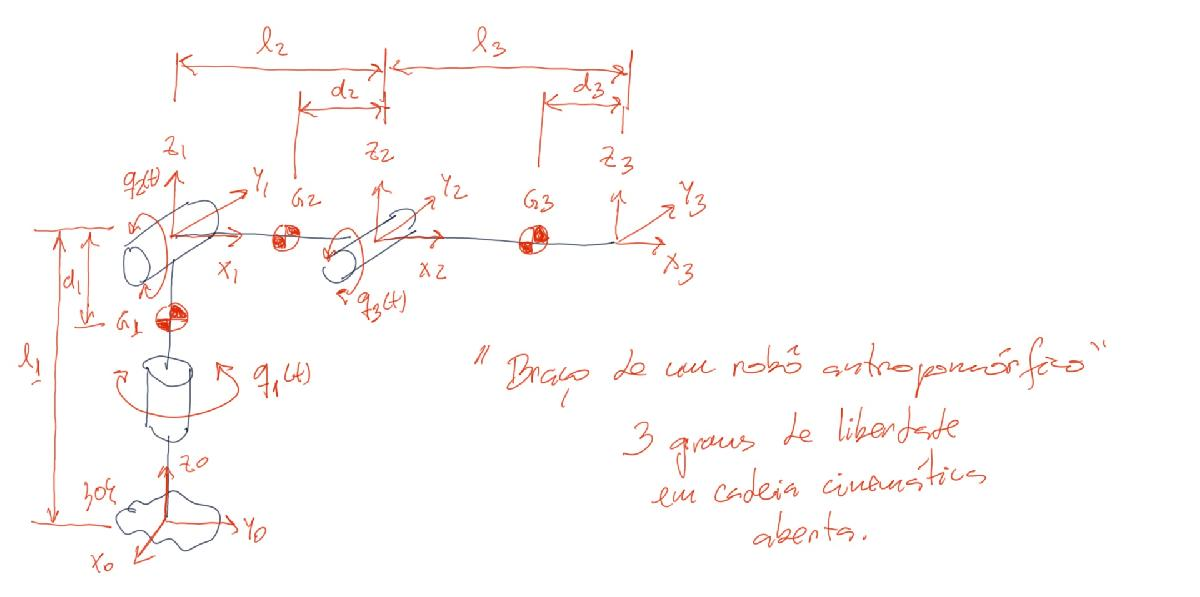

Figura 1 - Esquema do mecanismo de 3 graus de liberdade.

clear all, close all, clc

### Definição das variáveis e dos parâmetros do modelo

#### Comprimentos dos Elos:

syms L1 L2 L3

#### Coordenadas dos centros de massa:

syms d1 d2 d3

#### Coordenadas genaralizadas do mecanismo:

syms q1 q2 q3
syms dq1 dq2 dq3
syms d2q1 d2q2 d2q3
q = [q1; q2; q3];
dq = [dq1; dq2; dq3];
d2q = [d2q1; d2q2; d2q3];

### Estudar as transformações entre os referenciais

#### Diagrama de transformações

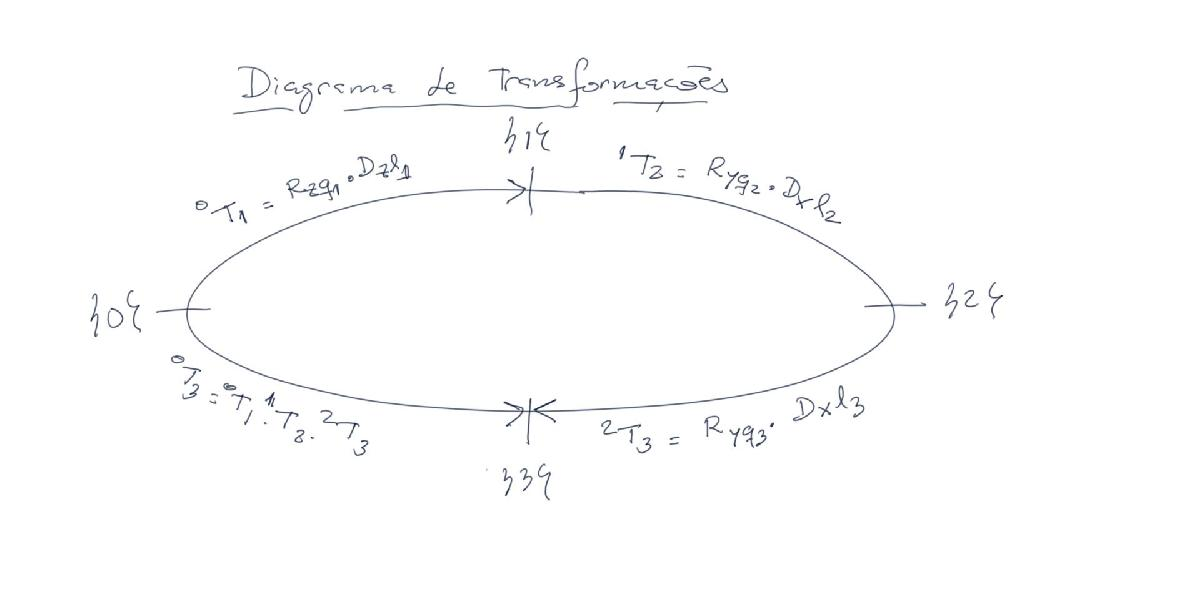

Figura 2 - Diagrama de transformações.

#### Definir as matrizes de transformação conforme o diagrama da Figura 1.

#### Transformação entre os referenciais {0} e {1}:

R1_0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1];
D1_0 = [1 0 0 0; 0 1 0 0; 0 0 1 L1; 0 0 0 1];
T1_0 = R1_0*D1_0;

#### Transformação entre os referenciais {1} e {2}:

R2_1 = [cos(q2) 0 sin(q2) 0; 0 1 0 0; -sin(q2) 0 cos(q2) 0; 0 0 0 1];
D2_1 = [1 0 0 L2; 0 1 0 0; 0 0 1 0; 0 0 0 1];
T2_1 = R2_1*D2_1;

#### Transformação entre os referenciais {2} e {3}:

R3_2 = [cos(q3) 0 sin(q3) 0; 0 1 0 0; -sin(q3) 0 cos(q3) 0; 0 0 0 1];
D3_2 = [1 0 0 L3; 0 1 0 0; 0 0 1 0; 0 0 0 1];
T3_2 = R3_2*D3_2;

#### Transformações entre todos os referenciais:

T2_0 = T1_0*T2_1;
T3_0 = T2_0*T3_2;

### Determinar o vetor posição até a origem dos referenciais, com relação ao referencial inercial.

#### Origem do referencial {1} com relação ao referencial {0}:

p1_0 = T1_0(1:3,4);

#### Origem do referencial {2} com relação ao referencial {0}:

p2_0 = T2_0(1:3,4);

#### Origem do referencial {3} com relação ao referencial {0}:

p3_0 = simplify(T3_0(1:3,4));

### Posição dos centros de massa, com relação ao referencial inercial.

#### Centro de massa do corpo 1 (G1):

pG1_1 = [0; 0; -d1; 1];
aux = T1_0*pG1_1;
pG1_0 = aux(1:3);
clear aux

#### Centro de massa do corpo 2 (G2):

pG2_2 = [-d2; 0; 0; 1];
aux = T2_0*pG2_2;
pG2_0 = aux(1:3);
clear aux

#### Centro de massa do corpo 3 (G3):

pG3_3 = [-d3; 0; 0; 1];
aux = T3_0*pG3_3;
pG3_0 = simplify(aux(1:3));
clear aux

### Velocidades e acelerações, lineares e angulares, dos referenciais móveis, com relação ao referencial inercial.

#### Velocidade linear do {1} :

JL1_0 = jacobian(p1_0,q);
v1_0 = JL1_0*dq;

#### Velocidade angular do {1}:

JA1_0 = [T1_0(1:3,3) zeros(3,1) zeros(3,1)];
w1_0 = JA1_0*dq;

#### Aceleração linear do {1}:

dJL1_0 = [jacobian(JL1_0(:,1),q)*dq jacobian(JL1_0(:,2),q)*dq jacobian(JL1_0(:,3),q)*dq];
dv1_0 = JL1_0*d2q + dJL1_0*dq;

#### Aceleração angular do {1}:

dJA1_0 = [jacobian(JA1_0(:,1),q)*dq jacobian(JA1_0(:,2),q)*dq jacobian(JA1_0(:,3),q)*dq];
dw1_0 = JA1_0*d2q + dJA1_0*dq;

#### Velocidade linear do {2} :

JL2_0 = jacobian(p2_0,q);
v2_0 = JL2_0*dq;

#### Velocidade angular do {2}:

JA2_0 = [T1_0(1:3,3) T2_0(1:3,2) zeros(3,1)];
w2_0 = JA2_0*dq;

#### Aceleração linear do {2}:

dJL2_0 = [jacobian(JL2_0(:,1),q)*dq jacobian(JL2_0(:,2),q)*dq jacobian(JL2_0(:,3),q)*dq];
dv2_0 = JL2_0*d2q + dJL2_0*dq;

#### Aceleração angular do {2}:

dJA2_0 = [jacobian(JA2_0(:,1),q)*dq jacobian(JA2_0(:,2),q)*dq jacobian(JA2_0(:,3),q)*dq];
dw2_0 = JA2_0*d2q + dJA2_0*dq;

#### Velocidade linear do {3} :

JL3_0 = jacobian(p3_0,q);
v3_0 = JL3_0*dq;

#### Velocidade angular do {3}:

JA3_0 = [T1_0(1:3,3) T2_0(1:3,2) T3_0(1:3,2)];
w3_0 = JA3_0*dq;

#### Aceleração linear do {3}:

dJL3_0 = [jacobian(JL3_0(:,1),q)*dq jacobian(JL3_0(:,2),q)*dq jacobian(JL3_0(:,3),q)*dq];
dv3_0 = JL3_0*d2q + dJL3_0*dq;

#### Aceleração angular do {3}:

dJA3_0 = [jacobian(JA3_0(:,1),q)*dq jacobian(JA3_0(:,2),q)*dq jacobian(JA3_0(:,3),q)*dq];
dw3_0 = JA3_0*d2q + dJA3_0*dq;

### Velocidades e acelerações lineares dos centros de massa.

#### Velocidade linear do ponto G1:

JLG1_0 = jacobian(pG1_0,q);
vG1_0 = JLG1_0*dq;

#### Aceleração linear do ponto G1:

dJLG1_0 = [jacobian(JLG1_0(:,1),q)*dq jacobian(JLG1_0(:,2),q)*dq jacobian(JLG1_0(:,3),q)*dq];
dvG1_0 = JLG1_0*d2q + dJLG1_0*dq;

#### Velocidade linear do ponto G2:

JLG2_0 = jacobian(pG2_0,q);
vG2_0 = JLG2_0*dq;

#### Aceleração linear do ponto G2:

dJLG2_0 = [jacobian(JLG2_0(:,1),q)*dq jacobian(JLG2_0(:,2),q)*dq jacobian(JLG2_0(:,3),q)*dq];
dvG2_0 = JLG2_0*d2q + dJLG2_0*dq;

#### Velocidade linear do ponto G3:

JLG3_0 = jacobian(pG3_0,q);
vG3_0 = JLG3_0*dq;

#### Aceleração linear do ponto G3:

dJLG3_0 = [jacobian(JLG3_0(:,1),q)*dq jacobian(JLG3_0(:,2),q)*dq jacobian(JLG3_0(:,3),q)*dq];
dvG3_0 = JLG3_0*d2q + dJLG3_0*dq;

### Energia cinética de cada elo.

#### Energia cinética de translação do Elo 1:

syms m1

Ect1 = 1/2*m1*transpose(vG1_0)*vG1_0;


#### Energia cinética de rotação do Elo 1:

syms Ixx1 Ixy1 Ixz1 Ixy1 Iyy1 Iyz1 Ixz1 Iyz1 Izz1

I1_1 = [Ixx1 -Ixy1 -Ixz1; -Ixy1 Iyy1 -Iyz1; -Ixz1 -Iyz1 Izz1];
R1_0 = T1_0(1:3,1:3);
I1_0 = simplify(R1_0*I1_1*transpose(R1_0));
Ecr1 = 1/2*transpose(w1_0)*I1_0*w1_0;

#### Energia cinética total do Elo 1:

Ec1 = simplify(Ect1 + Ecr1);

#### Energia cinética de translação do Elo 2:

syms m2

Ect2 = 1/2*m2*transpose(vG2_0)*vG2_0;


#### Energia cinética de rotação do Elo 2:

syms Ixx2 Ixy2 Ixz2 Ixy2 Iyy2 Iyz2 Ixz2 Iyz2 Izz2

I2_2 = [Ixx2 -Ixy2 -Ixz2; -Ixy2 Iyy2 -Iyz2; -Ixz2 -Iyz2 Izz2];
R2_0 = T2_0(1:3,1:3);
I2_0 = simplify(R2_0*I2_2*transpose(R2_0));
Ecr2 = 1/2*transpose(w2_0)*I2_0*w2_0;

#### Energia cinética total do Elo 2:

Ec2 = simplify(Ect2 + Ecr2);

#### Energia cinética de translação do Elo 3:

syms m3

Ect3 = 1/2*m3*transpose(vG3_0)*vG3_0;


#### Energia cinética de rotação do Elo 3:

syms Ixx3 Ixy3 Ixz3 Ixy3 Iyy3 Iyz3 Ixz3 Iyz3 Izz3

I3_3 = [Ixx3 -Ixy3 -Ixz3; -Ixy3 Iyy3 -Iyz3; -Ixz3 -Iyz3 Izz3];
R3_0 = T3_0(1:3,1:3);
I3_0 = simplify(R3_0*I3_3*transpose(R3_0));
Ecr3 = 1/2*transpose(w3_0)*I3_0*w3_0;

#### Energia cinética total do Elo 2:

Ec3 = simplify(Ect3 + Ecr3);

#### Energia potencial do Elo 1:

syms g

grav = [0; 0; -g];
Ep1 = -m1*transpose(grav)*pG1_0;

#### Energia potencial do Elo 2:

syms g

Ep2 = -m2*transpose(grav)*pG2_0;

#### Energia potencial do Elo 3:

syms g

Ep3 = -m3*transpose(grav)*pG3_0;

#### Energia dissipada na junta 1:

syms c1

Ed1 = 1/2*c1*dq1^2;

#### Energia dissipada na junta 2:

syms c2

Ed2 = 1/2*c2*dq2^2;

#### Energia dissipada na junta 3:

syms c3

Ed3 = 1/2*c3*dq3^2;

### Lagrangeano do sistema e Energia dissipada:

L = (Ec1 + Ec2 + Ec3) - (Ep1 + Ep2 + Ep3);
Ec = Ec1 + Ec2 + Ec3;
Ep = Ep1 + Ep2 + Ep3;
Ed = Ed1 + Ed2 + Ed3;

### Equações de movimento:

T = M*d2q + H + G + D

for n = 1:1:3,
    G(n,1) = diff(Ep,q(n)); % Contribuição da gravidade para o momento de força líquido nas juntas
    D(n,1) = diff(Ed,dq(n)); % Contribuição do atrito para o momento de força líquido nas juntas
    H2(n,1) = -diff(Ec,q(n)); % Contribuição da aceleração centrífuga (primeira parcela) para o momento de força líquido nas juntas
end

soma = 0;
for n = 1:1:3,
    for k = 1:1:3,
        M(n,k) = diff(diff(Ec,dq(n)),dq(k)); % Matriz de inércia - Contribuição da inércia para o omento de força líquido nas juntas
        aux = diff(diff(Ec,dq(n)),q(k))*dq(k);
        soma  =soma + aux;
    end
    H1(n,1) = soma; % Contribuição da aceleração centrífuga (segunda parcela) e a aceleração de Coriolis para o momento de força líquido nas juntas
end
H = H1 + H2; % Contribuição das acelerações centrífuga e de coriolis total para o momento de força líquido nas juntas

T = M*d2q + H + G + D; % Momento de força total nas juntas

% M(1,1) = diff(diff(Ec,dq1),dq1)
% M(1,2) = diff(diff(Ec,dq1),dq2)
% M(1,3) = diff(diff(Ec,dq1),dq3)
% 
% M(2,1) = diff(diff(Ec,dq2),dq1)
% M(2,2) = diff(diff(Ec,dq2),dq2)
% M(2,3) = diff(diff(Ec,dq2),dq3)
% 
% M(3,1) = diff(diff(Ec,dq3),dq1)
% M(3,2) = diff(diff(Ec,dq3),dq2)
% M(3,3) = diff(diff(Ec,dq3),dq3)

% H1(1,1) = diff(diff(Ec,dq1),q1)*dq1 + diff(diff(Ec,dq1),q2)*dq2 + diff(diff(Ec,dq1),q3)*dq3
% H1(2,1) = diff(diff(Ec,dq2),q1)*dq1 + diff(diff(Ec,dq2),q2)*dq2 + diff(diff(Ec,dq2),q3)*dq3
% H1(3,1) = diff(diff(Ec,dq3),q1)*dq1 + diff(diff(Ec,dq3),q2)*dq2 + diff(diff(Ec,dq3),q3)*dq3


